# **Signals and Systems Lab Report**

**Q1.1: **Determine the period of $x(t)$ theoretically and check hat it agrees with the period measured directly in the plot of $x$.

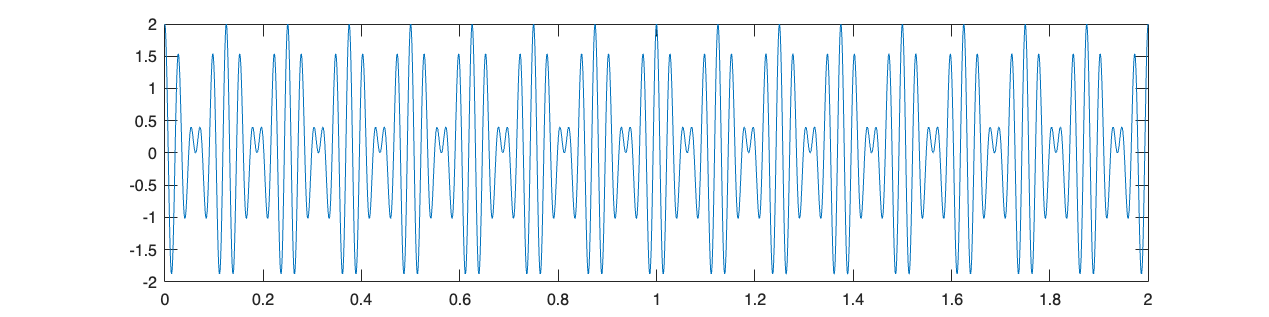

samplerate = 16e3; % Hz
t = (0:1/samplerate:2); % s
f1 = 32; % Hz
f2 = 40; % Hz
x = cos(2*pi*f1*t) + cos(2*pi*f2*t);
figure('Units', 'pixels', 'Position', [0, 0, 1000, 500]); 
plot(t,x)

%[xi, yi] = ginput;
period = mean(diff(xi))

period = 0.1250

Theoretically, the fundamental period of the signal is the least common multiple (LCM) of the fundamental periods of each cosine.

When working with rational numbers (like the fundamental periods for each of the cosines, as they are the inverse of their frequencies), $\text{LCM} = \frac{\text{LCM of numerators } (=1)}{\text{GCD of denominators}}$.

theoretical_period = 1/gcd(f1, f2)

theoretical_period = 0.1250

The period we measured, as the mean of the subsequent differences between periodic locations in the signal, agrees with the theoretical period we calculated above.

**Q1.2:** As discussed above, this "continuous-time" signal `x` in Matlab is actually a discrete-time signal. Determine its theoretical period in samples and check against the direct measurement taken from `plot(x)`.

% Code

If you now downsample it by a factor of 3, what will be the period of `y`, in samples?

% Code

Why does this only seemingly disagree with direct measurement from `plot(y)`?

% Code

**Q1.3:** Determine the frequencies of C4, E4, F#4, G4, B4. 

A4 = 440; % Hz
ratio = 2^(1/12);

% TODO: I should change this code into a reusable function that takes in a
% parameter which is like distance_from_A4...

C4 = A4 * ratio^(-9);
E4 = A4 * ratio^(-5);
Fs4 = A4 * ratio^(-3);
G4 = A4 * ratio^(-2);
B4 = A4 * ratio^(2);
F4 = A4*ratio^(-4)

F4 = 349.2282

Use the `seqsin` function to generate a sequence of sinusoids and silence gaps. Create x as the following sequence and listen to the resulting signal:


$$\text{R(0.7), E4(0.25), E4(0.25), F4(0.25), F\#4(0.5), A4(0.25),} \\

\text{F\#4(0.25), A4(0.25), F\#4(0.25), F\#4(0.25), F4(0.25),} \\

\text{E4(0.25), B4(0.25), E4(0.25), E4(0.5), R(0.7)}$$


x = seqsin(samplerate, 0, 0.7, E4, 0.25, E4, 0.25, F4, 0.25, Fs4, 0.5, A4, 0.25, ...
            Fs4, 0.25, A4, 0.25, Fs4, 0.25, Fs4, 0.25, F4, 0.25, ...
            E4, 0.25, B4, 0.25, E4, 0.25, E4, 0.5, 0, 0.7);
soundsc(x, samplerate)

**Q1.4:** Function $u$ can handle any aﬃne transformation of the time variable. Yet, $u(at+ b)$ with arbitrary $a$ and $b$ can simply be written as $u(\pm t-t_0)$ with suitable $t_0$. 

Justify this and find the apropriate values of factor $\pm 1$and $t_0$ given $a$ and $b.$ 

Check your results experimentally for diﬀerent choices of $a$ and $b$.

% Code

The parameter $\Delta$ defines the width of the region around $t= 0$ where $u_\Delta$ transitions from $0$ to $1$, and where $\delta_\Delta$ has nonzero support.

Generate a time variable spanning a symmetric interval around zero and check `plot(t,deltaD(t-t0,D))` for diﬀerent choices of `D` and `t0`.

% Code

Visualise the approximate impulse `deltaD(a*t,D)` for diﬀerent values of the scaling parameter `a`. 

% Code

Explain why these results are consistent with the following known property of the ideal impulse.

...